filename = "Final_Pelvis_Impact_Velocity_Data.xlsx";

sheets = {"Choi et al 2015", "Robinovitch et al 2004", "Robinovitch et al 2003", ...
          "Hsiao & Robinovitch 1998", "Wang et al 2017", "Smeesters et al 2001", ...
          "Michaels et al 2025", "Khorami et al 2023"};

data = cell(1, length(sheets));

for i = 1:length(sheets)
    temp = readtable(filename, "Sheet", sheets{i});

    n = height(temp);

    temp.Study = repmat(string(sheets{i}), n, 1);

    data{i} = temp;
end

data = vertcat(data{:});

data.Sex = categorical(data.Sex);
data.Fall_Direction = categorical(data.Fall_Direction);
data.Cause_Of_Fall = categorical(data.Cause_Of_Fall);
data.Activity_At_Time_Of_Fall = categorical(data.Activity_At_Time_Of_Fall);
data.Study = categorical(data.Study);

fig_width = 90/25.4;
fig_height = 90/25.4;
font = 'Calibri';
font_size = 9;
cb_color = [0.0000, 0.4470, 0.7410];

fig1 = figure('Units','inches','Position',[1 1 fig_width fig_height]);

histogram(data.Age,...
    'BinWidth',5,...
    'FaceColor',cb_color,...
    'EdgeColor','k',...
    'LineWidth',0.5);

xlabel('Age (years)',...
    'FontName',font,...
    'FontSize',font_size);

ylabel('Frequency',...
    'FontName',font,...
    'FontSize',font_size);

title('');

set(gca,...
    'FontName',font,...
    'FontSize',font_size,...
    'LineWidth',0.5);

box on;
grid on;
exportgraphics(fig1,'fig2a.tiff','Resolution',1000)

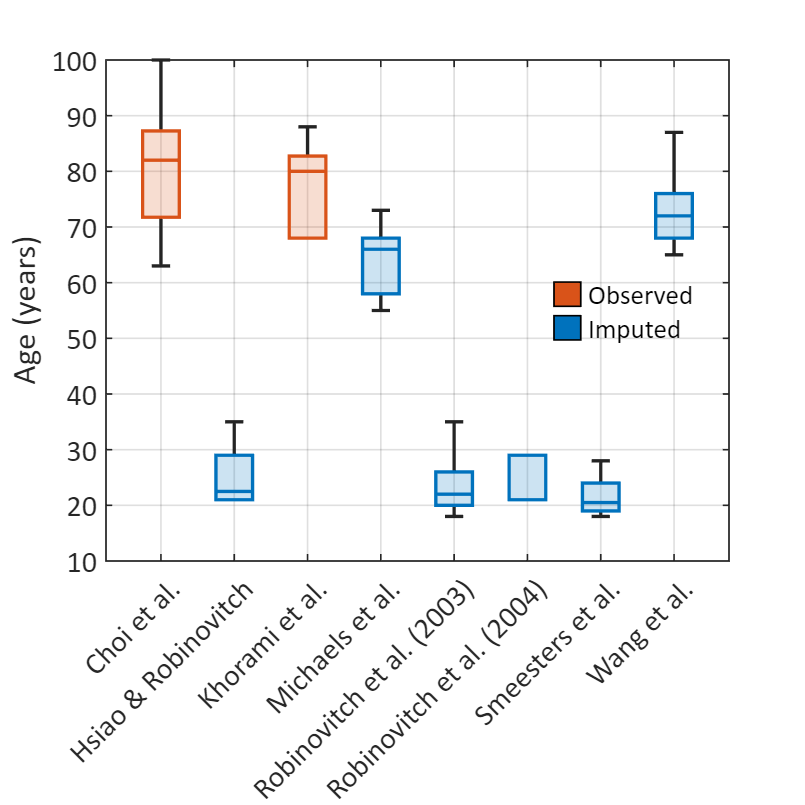

fig2 = figure('Units','inches','Position',[1,1,fig_width,fig_height]);

study_order = { ...
    'Choi et al 2015', ...
    'Hsiao & Robinovitch 1998', ...
    'Khorami et al 2023', ...
    'Michaels et al 2025', ...
    'Robinovitch et al 2003', ...
    'Robinovitch et al 2004', ...
    'Smeesters et al 2001', ...
    'Wang et al 2017'};

plot_labels = { ...
    'Choi et al.', ...
    'Hsiao & Robinovitch', ...
    'Khorami et al.', ...
    'Michaels et al.', ...
    'Robinovitch et al. (2003)', ...
    'Robinovitch et al. (2004)', ...
    'Smeesters et al.', ...
    'Wang et al.'};

data.Study = categorical(data.Study,...
    study_order,'Ordinal',true);

hold on

obs_idx = ismember(string(data.Study), ...
    ["Choi et al 2015","Khorami et al 2023"]);

hObs = boxchart(data.Study(obs_idx), ...
                data.Age(obs_idx), ...
                'BoxFaceColor',[0.8500 0.3250 0.0980]);

hImp = boxchart(data.Study(~obs_idx), ...
                data.Age(~obs_idx), ...
                'BoxFaceColor',cb_color);

ylabel('Age (years)',...
    'FontName',font,...
    'FontSize',font_size);

title('');

ax = gca;
ax.FontName = font;
ax.FontSize = font_size;
ax.LineWidth = 0.5;

ax.XTickLabel = plot_labels;

xtickangle(45)


% legend([hObs,hImp],...
%        {'Observed','Imputed'},...
%        'Location','best',...
%        'FontName',font,...
%        'FontSize',8,...
%        'Box','off');

dummyObs = patch(NaN,NaN,[0.8500 0.3250 0.0980]);
dummyImp = patch(NaN,NaN,cb_color);
lgd = legend([dummyObs,dummyImp],...
    {'Observed','Imputed'},...
    'Location','best',...
    'Box','off');

lgd.ItemTokenSize = [8 8];

grid on
box on
exportgraphics(fig2,'fig2b.tiff','Resolution',1000)